# Lab 2 - Visión por Computador

**Juan Carlos Soriano (1493037) - Jorge Giménez (1493035)**

Primeramente, cargamos y mostramos la imagen sobre la que queremos aplicar el algoritmo.

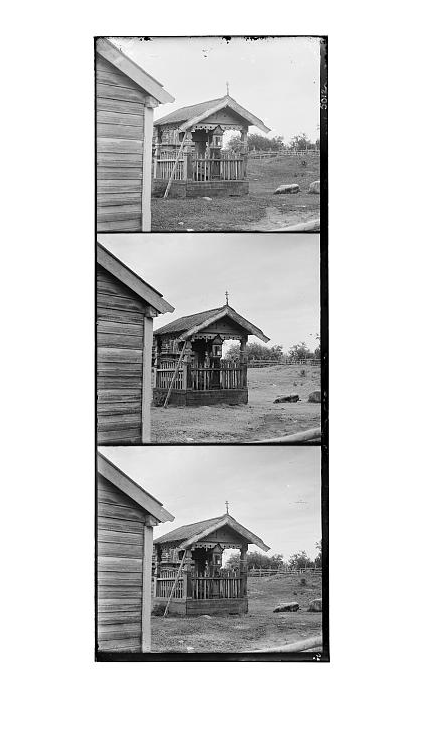

imagePath = "./inputImage1.jpg";
inputImage = im2double(imread(imagePath));
imshow(inputImage, []);

### 1- Segmentación de las 3 *subimágenes*

El primer paso será conseguir separar las 3 *subimágenes* de la* imagen total* (esta imagen vertical que contiene 3 imágenes más pequeñas dentro suyo que podemos ver al principio del *script* al ejecutarlo).

En el siguiente código se hacen las siguientes asunciones:

- Que las *subimágenes* están eprfectamente colocadas ocupando cada una 1/3 de la *imagen total*.

- Que se ordenan en el orden BGR de arriba hacía abajo (encontraod en la web).

tmp = size(inputImage);
subImageHeight = floor(tmp(1)/3);

b = inputImage(1:subImageHeight+1,:);
g = inputImage(subImageHeight:subImageHeight*2,:);
r = inputImage(subImageHeight*2:subImageHeight*3,:);

Podemos visualizar las 3 *subimágenes *obtenidas mediante esta segmentación tan sencilla:

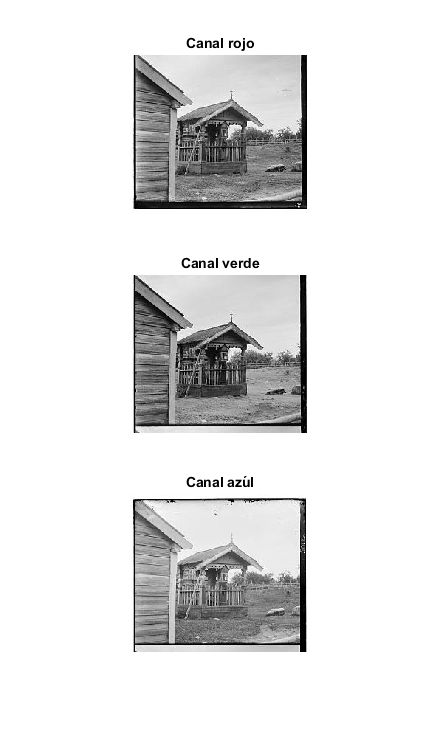

subplot(3, 1, 1);
imshow(r);
title("Canal rojo")
subplot(3, 1, 2);
imshow(g);
title("Canal verde")
subplot(3, 1, 3);
imshow(b);
title("Canal azul")

figure

Si superponemos las imagenes en el orden correcto tal y como las habríamos obtenido ahora, tedríamos el siguiente resultado:

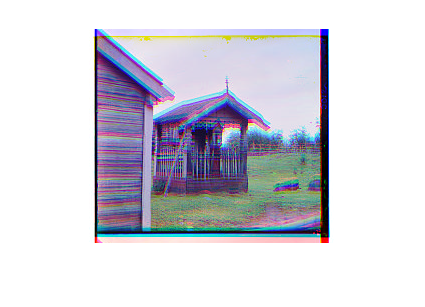

firstComposition = cat(3, r, g, b);
imshow(firstComposition);

Se puede ver como la imagen toma color pero no se ve demasiado bien debido a que los 3 canales no acaban de estar bien centrados entre si.

### 2- Centrado de las 3 *subimágenes*